**Homework 1 Phys4001**

Steven Henderson

9/12/2024

**1.**

People exhale, cough or sneeze particles ranging from 0.1 μm to 1000 μm in

diameter. Consider spherical droplets of diameters 2 μm (sometimes referred

to as aerosols) and 400 μm with the same density as water. The drag force

may be taken as $F_{\textrm{Drag}} =-\textrm{bv}-{\textrm{cv}}^2$ where the expressions for b and c were

given in lecture. The motion is assumed to be one-dimensional, vertically

downward, and starting from rest.


$$b=6\pi \eta R$$



$$c=\frac{1}{2}c_D^{\;} \rho A$$


(i) In each case, solve for the vertical terminal velocity $v_t$ analytically, and

then calculate it numerically.

Terminal velocity is reached when $F_{\textrm{gravity}} ={-F}_{\textrm{Drag}}$ and therefore the object is under no acceleration.

$F_{\textrm{gravity}} =\textrm{mg}$ (assume g)


$$F_{\textrm{Drag}} =-\textrm{bv}-{\textrm{cv}}^2 =-F_{\textrm{gravity}} =-\textrm{mg}$$


solve for velocity:


$${-\textrm{cv}}^2 -\textrm{bv}+\textrm{mg}=0$$



$$v=\frac{b\pm \sqrt{{\left(b\right)}^2 -4\left(-c\right)\left(\textrm{mg}\right)}}{-2c}=\frac{b\pm \sqrt{b^2 +4\textrm{cmg}}}{-2c}$$


Droplet of 2 microns

diameters = [2 * 10^-6, 400 * 10^-6];
viscosity = 1.8*10^-5;
coefficient_of_drag = 0.47;
radius = diameters ./ 2;
density_water = 1000;
volume = 4/3 * pi * radius.^3;
mass = volume * density_water;
density_air = 1.225;
area = pi * radius.^2;
b = 6 * pi * viscosity * radius;
c = 0.5 * coefficient_of_drag * density_air * area;
g = 9.8;
v = (b - sqrt(b.^2 + 4*c.*mass*g)) ./ (-2*c) % Quadratic formula from above where the first number in the array is the smaller droplet and the second is the larger one

v =     0.0001    2.2177


(ii) Determine whether laminar or turbulent flow dominates for each droplet

size.

*Laminar*


$$F=-\textrm{bv}$$


*Turbulent*


$$F=-{\textrm{cv}}^2$$


format long
F_lam = -b.*v

F_lam = 1.0e-06 *

  -0.000000041050131  -0.150487725543369


F_turb = -c.*v.^2

F_turb = 1.0e-06 *

  -0.000000000000013  -0.177913426511884


For the smaller drop it seems that laminar dominates but, for the larger one it seems the larger one dominates.

(iii) Using Matlab, make a log-log plot of the vertical terminal velocity in

units of cm/s versus droplet diameter ranging from 0.1 μm to 10,000 μm.

[To create such a large span of diameters in Matlab you would want to

use a function called ‘logspace’. To make a log-log plot use the command

‘loglog(X,Y,LineSpec)’ instead of ‘plot(X,Y,LineSpec)’. Place 10 tic marks

per decade.] Note the change of slope where the smooth transition between

laminar and turbulent flow occurs. The reason for plotting the larger droplets

(up to 1 cm!) is to more clearly see the transition from laminar to turbulent

flow. If there is an updraft greater than the terminal velocity the droplet will

rise rather than fall, and horizontal air currents could carry them far away

from their original position.

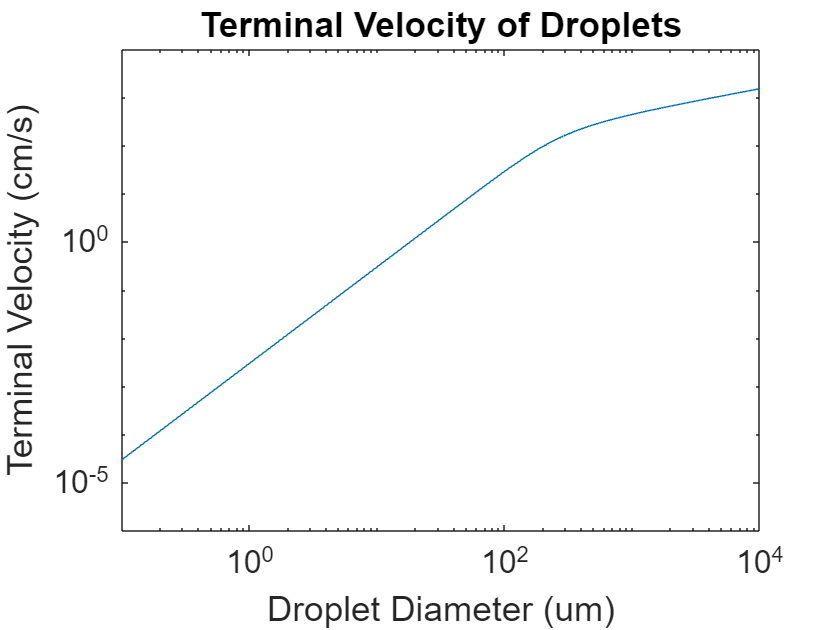

diameters_microns = logspace(-1, 4);
diameters = diameters_microns * 10^-6;
viscosity = 1.8*10^-5;
coefficient_of_drag = 0.47;
radius = diameters ./ 2;
volume = 4/3 * pi * radius.^3;
mass = volume * density_water;
area = pi * radius.^2;
b = 6 * pi * viscosity * radius;
c = 1/2 * coefficient_of_drag * density_air * area;
v = (b - sqrt(b.^2 + 4*c.*mass*g)) ./ (-2*c) * 100;
loglog(diameters_microns, v)
xlim([10^-1, 10^4])
set(gca, 'fontsize', 16)
xlabel('Droplet Diameter (um)')
title('Terminal Velocity of Droplets')
ylabel('Terminal Velocity (cm/s)')

**2.** 

A perfectly flexible chain has length L, mass M , and constant

mass per unit length $\frac{M}{L}$. At time t = 0 it is at rest with a length $x_0$ < L

hanging vertically over the edge of a table.

(i) Neglecting friction, compute the length x(t) hanging over the edge after

a time t. Assume that the horizontal and vertical sections remain straight

during the motion. At what time $t_L$ is x($t_L$) = L?

$m_2 =x\left(t\right)\left(\frac{M}{L}\right)$    -    Mass of hanging part of chain


$$m_1 =M-m_2 =\frac{M}{L}\left(L-x\left(t\right)\right)$$


$F_{\textrm{net}} =m_2 g$    -    Only force acting upon the chain is the force of the mass hanging


$$m_2 g=\textrm{Ma}$$


$a=\frac{m_2 g}{M}=\frac{x\left(t\right)\frac{M}{L}g}{M}=\frac{\textrm{gx}\left(t\right)}{L}={x^{\prime } }^{\prime } \left(t\right)$    -    Differential

$x\left(t\right)={\textrm{Ae}}^{\textrm{ct}}$    -    Guess


$${x^{\prime } }^{\prime } \left(t\right)={\textrm{Ac}}^2 e^{\textrm{ct}}$$


$x\left(t\right)={\textrm{Ae}}^{\sqrt{\frac{g}{L}t}} +{\textrm{Be}}^{-\sqrt{\frac{g}{L}t}}$    -    Add negative part for posterity


$$x^{\prime } \left(t\right)=A\sqrt{\frac{g}{L}}e^{\sqrt{\frac{g}{L}t}} -B\sqrt{\frac{g}{L}}e^{-\sqrt{\frac{g}{L}}t}$$



$$x\left(0\right)=x_0 =A+B$$



$$x^{\prime } \left(0\right)=0=A\sqrt{\frac{g}{L}}-B\sqrt{\frac{g}{L}}$$



$$A-B=0$$



$$\begin{array}{l}
x\left(t\right)=\frac{x\left(0\right)}{2}e^{\sqrt{\frac{g}{L}}t} +\frac{x\left(0\right)}{2}e^{-\sqrt{\frac{g}{L}}t} =\frac{x\left(0\right)}{2}\left(e^{\sqrt{\frac{g}{L}}t} +e^{-\sqrt{\frac{g}{L}}t} \right)=L\\
x\left(0\right)\cosh \left(\sqrt{\frac{g}{L}}t\right)=L\\
\textrm{arccosh}\left(\frac{L}{x\left(0\right)}\right)=\sqrt{\frac{g}{L}}t\\
\sqrt{\frac{L}{g}}\textrm{arccosh}\left(\frac{L}{x\left(0\right)}\right)=t_L 
\end{array}$$


(ii) More realistically, there is a frictional force between the chain and table

top with kinetic and static coefficients of friction $\mu_k$< $\mu_s$. What is the max-

imum value of $x_0$, called $x_c$, such that the chain does not move?


$$F_{\textrm{Net}} =F_{\textrm{Friction}} +F_{\textrm{gravity}} =0$$



$$F_{\textrm{gravity}} =m_2 g$$



$$\begin{array}{l}
|F_{\textrm{drag}} |\le \mu_s N=-\mu_s \left(m_1 \right)g\\
\lambda =\frac{M}{L}\\
F_{\textrm{drag}} +F_{\textrm{gravity}} =0=\lambda x\left(t\right)g-\mu_s \lambda \left(L-x\left(t\right)\right)g\\
0=\lambda x\left(t\right)g-\mu_s \lambda {\textrm{Lg}} +\mu_s \lambda \textrm{gx}\left(t\right)=x\left(t\right)\left(\lambda g+\mu_s \lambda g\right)-\mu_s \lambda {\textrm{Lg}} \\
\frac{\mu_s L }{\left(1+\mu_s \right)}=x_0 
\end{array}$$


(iii) At t = 0 and $x_0$ = $x_c$we give the chain a tiny velocity $v_i$ so that it

immediately begins to move and the coefficient of friction changes from $\mu_s$to $\mu_k$. What now is the length hanging over the edge after a time t?

(You might want to try this out experimentally at home.)

$\begin{array}{l}
\lambda =\frac{M}{L}\\
F_k =\mu_k N=\mu_k \lambda \left(L-x\left(t\right)\right)g\\
F_g =\lambda x\left(t\right)g\\
{{\textrm{Mx}}^{\prime } }^{\prime } \left(t\right)=\lambda x\left(t\right)g-\mu_k \lambda \left(L-x\left(t\right)\right)g\\
{{\textrm{Mx}}^{\prime } }^{\prime } \left(t\right)=\lambda x\left(t\right)g-\mu_k \lambda \textrm{Lg}+\mu_k \lambda x\left(t\right)g=\left(\lambda g{+\mu }_k \lambda g\right)x\left(t\right)-\mu_k \lambda \textrm{Lg}\\
{{\textrm{Mx}}^{\prime } }^{\prime } \left(t\right)-\left(\lambda g{+\mu }_k \lambda g\right)x\left(t\right)=-\mu_k \lambda \textrm{Lg}\\
{{\textrm{Mx}}^{\prime } }^{\prime } \left(t\right)-\left(\lambda g{+\mu }_k \lambda g\right)x\left(t\right)=0\\
{x^{\prime } }^{\prime } \left(t\right)-\frac{\left(\lambda g{+\mu }_k \lambda g\right)}{M}x\left(t\right)=0\\
\omega^2 =\frac{\left(\lambda g{+\mu }_k \lambda g\right)}{M}\Rightarrow {x^{\prime } }^{\prime } \left(t\right)-\omega^2 x\left(t\right)=0\\
x_c \left(t\right)={\textrm{Ae}}^{\omega t} +{\textrm{Be}}^{-\omega t} \\
x_p =c=C\\
M\left(0\right)-\left(\lambda g{+\mu }_k \lambda g\right)C=-\mu_k \lambda \textrm{Lg}
\end{array}$    - find homogenous answer and particular and combine


$$\begin{array}{l}
C=\frac{\mu_k \lambda L}{\lambda {+\mu }_k \lambda }\\
x\left(t\right)=x_c +x_p ={\textrm{Ae}}^{\omega t} +{\textrm{Be}}^{-\omega t} +\frac{\mu_k L}{1{+\mu }_k }\\
\frac{\mu_s L }{\left(1+\mu_s \right)}=A+B+\frac{\mu_k L}{1{+\mu }_k }
\end{array}$$


3. (20 points) Consider a drag force that is linear in the velocity of an object

of mass m: Fdrag = −bv. The object is thrown with an initial velocity v0

that has nonzero components both horizontal and vertically upward.

(i) Derive the position of the object in both horizontal and vertical compo-

nents as a function of time.

Horizontal:


$$\begin{array}{l}
F_{\textrm{Net}} =-bv_x =m\frac{dv_x }{\textrm{dt}}\\
\frac{dv_x }{v_x }=-\frac{b}{m}\textrm{dt}\\
\ln |v_x |=-\frac{b}{m}t+C\\
v_x ={\textrm{Ae}}^{-\frac{b}{m}t} =v_{0,x} e^{-\frac{b}{m}t} \\
x\left(t\right)=-\frac{m}{b}v_{0,x} e^{-\frac{b}{m}t} +C\\
x\left(0\right)=0\\
x\left(t\right)=\frac{m}{b}v_{0,\;x} \left(1-e^{-\frac{b}{m}t} \right)
\end{array}$$


Vertical


$$\begin{array}{l}
-bv_y -\textrm{mg}=m\frac{dv_y }{\textrm{dt}}\\
\frac{dv_y }{\textrm{dt}}=-\frac{b}{m}v_y -g\\
\frac{dv_y }{\textrm{dt}}+\frac{b}{m}v_y =0\\
v_{\textrm{yc}} \left(t\right)=v_{0,\;y} e^{-\frac{b}{m}t} \\
\frac{dv_{\textrm{yp}} }{\textrm{dt}}=0=-\frac{b}{m}v_{\textrm{yp}} -g\\
v_{\textrm{yp}} =-\frac{\textrm{mg}}{b}\\
v_y \left(t\right)=v_{0,\;y} e^{-\frac{b}{m}t} -\frac{\textrm{mg}}{b}\\
y\left(t\right)=\int v_{0,\;y} e^{-\frac{b}{m}t} -\frac{\textrm{mg}}{b}\textrm{dt}\\
y\left(t\right)=-\frac{m}{b}v_{0,\;y} e^{-\frac{b}{m}t} -\frac{\textrm{mg}}{b}t+C\\
y\left(0\right)=0\\
y\left(t\right)=\frac{m}{b}v_{0,\;y} \left(1-e^{-\frac{b}{m}t} \right)-\frac{\textrm{mg}}{b}t
\end{array}$$


(ii) Find the distance the object has moved in the horizontal direction after

three characteristic time constants have elapsed, that is when t = 3τ where

τ ≡ m/b.


$$\begin{array}{l}
y\left(t\right)=Tv_{0,\;y} \left(1-e^{-3} \right)-{3T}^2 g\\
x\left(t\right)=Tv_{0,\;x} \left(1-e^{-3} \right)
\end{array}$$
